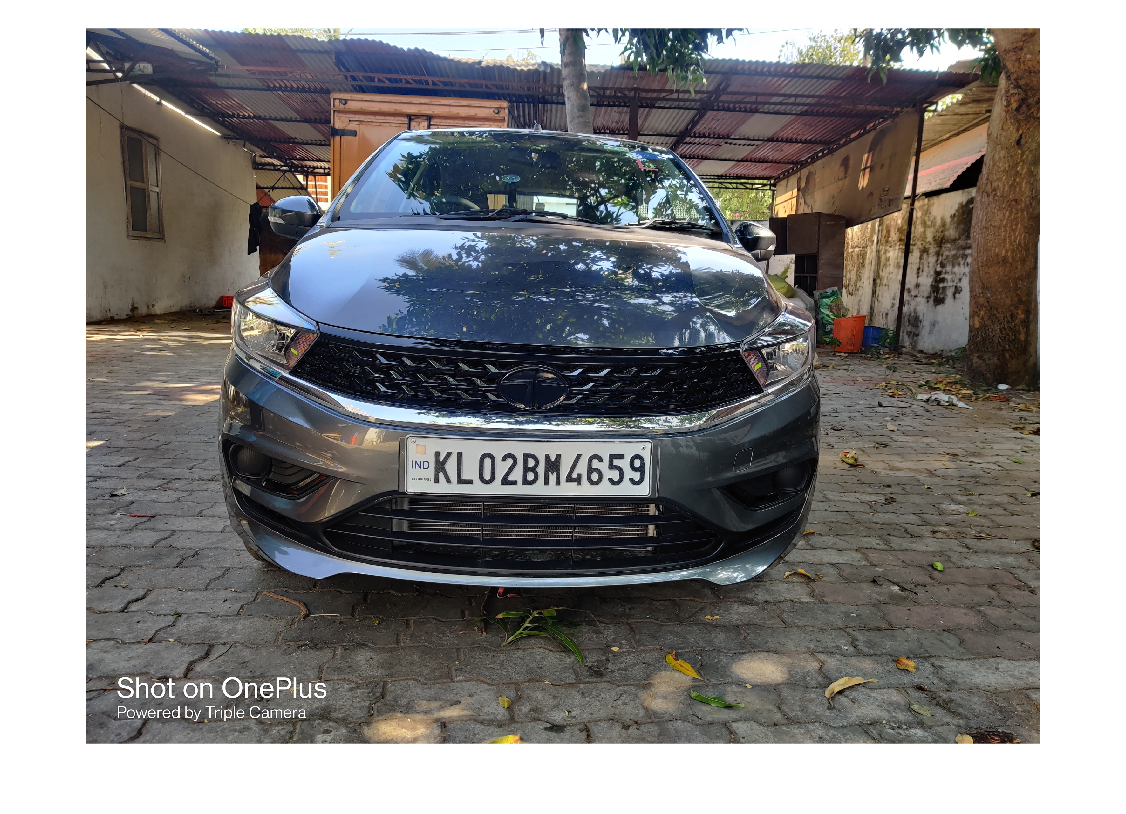

p = imread("data\Sample_Images\Datacluster_number_plates (16).jpg");
img = p(:,:,1);
imshow(p)

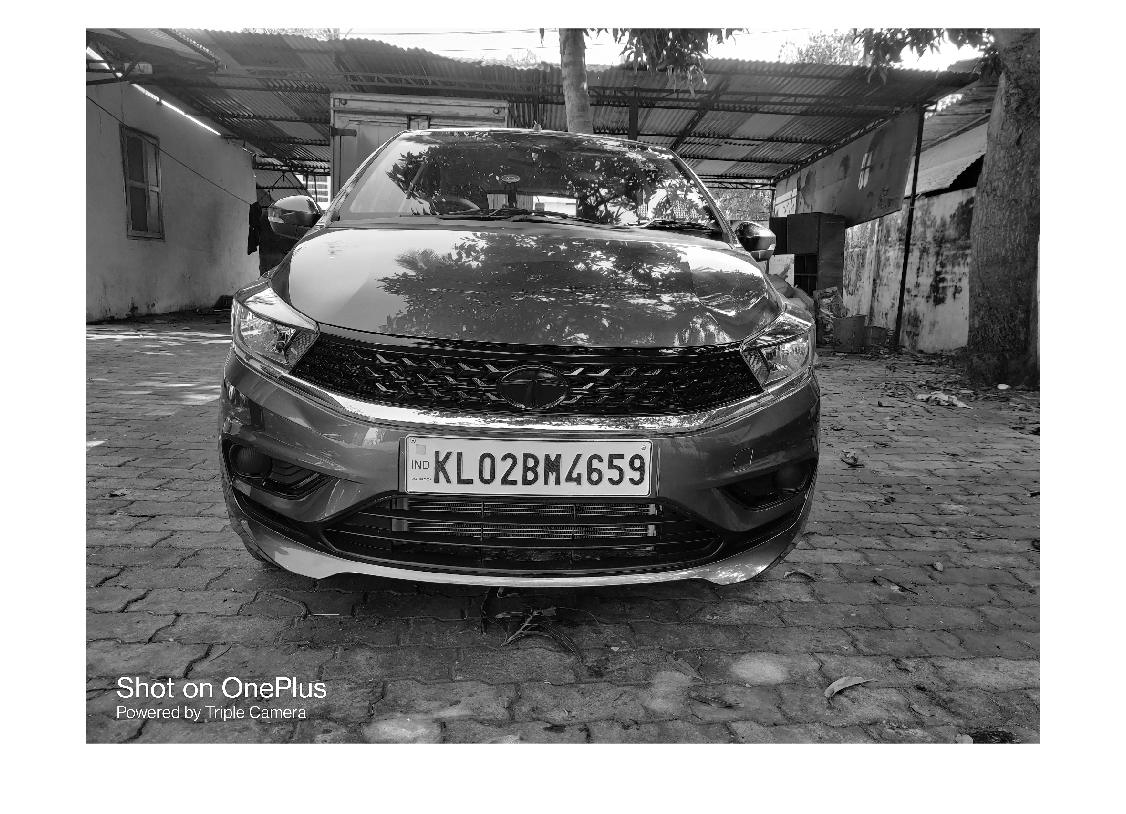

img(:, :) = 0.114 * p(: , : , 1) + 0.587 * p(: , : , 2) + 0.299 * p(: , : , 3);
imshow(img)

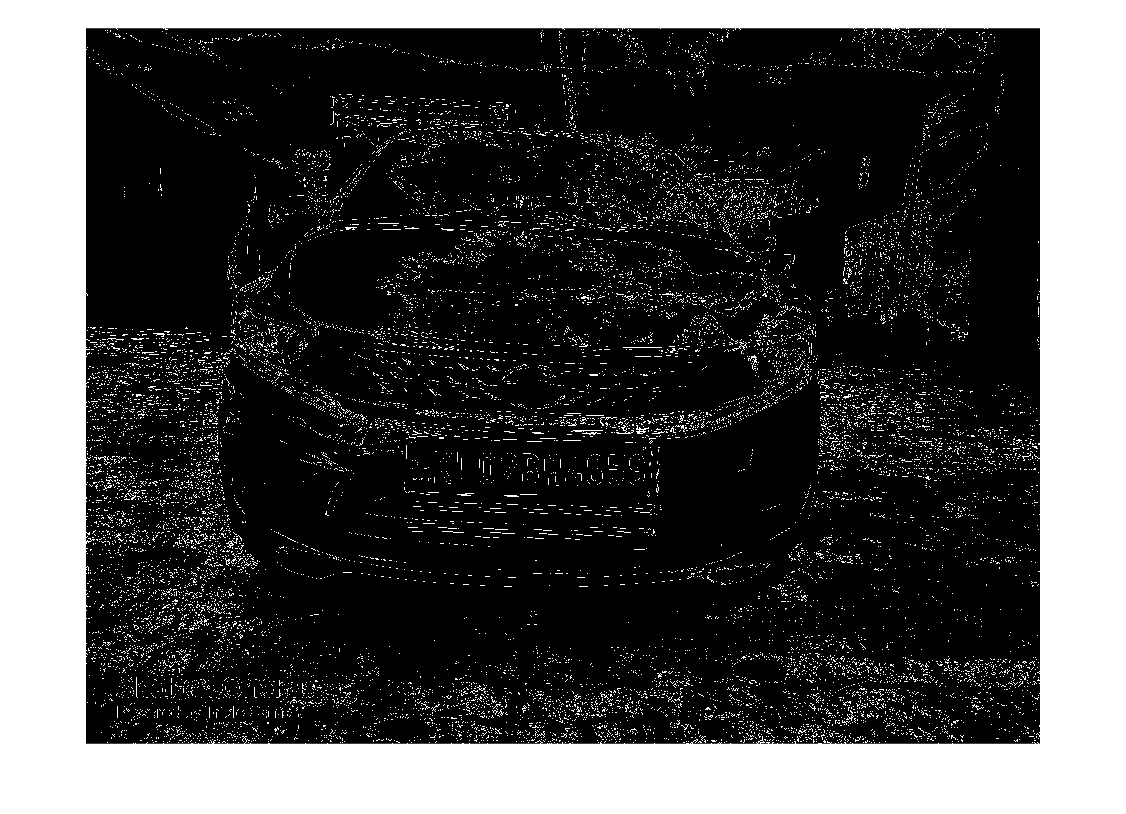

mbin = imbinarize(img);
im = edge(mbin, 'prewitt');
imshow(im)

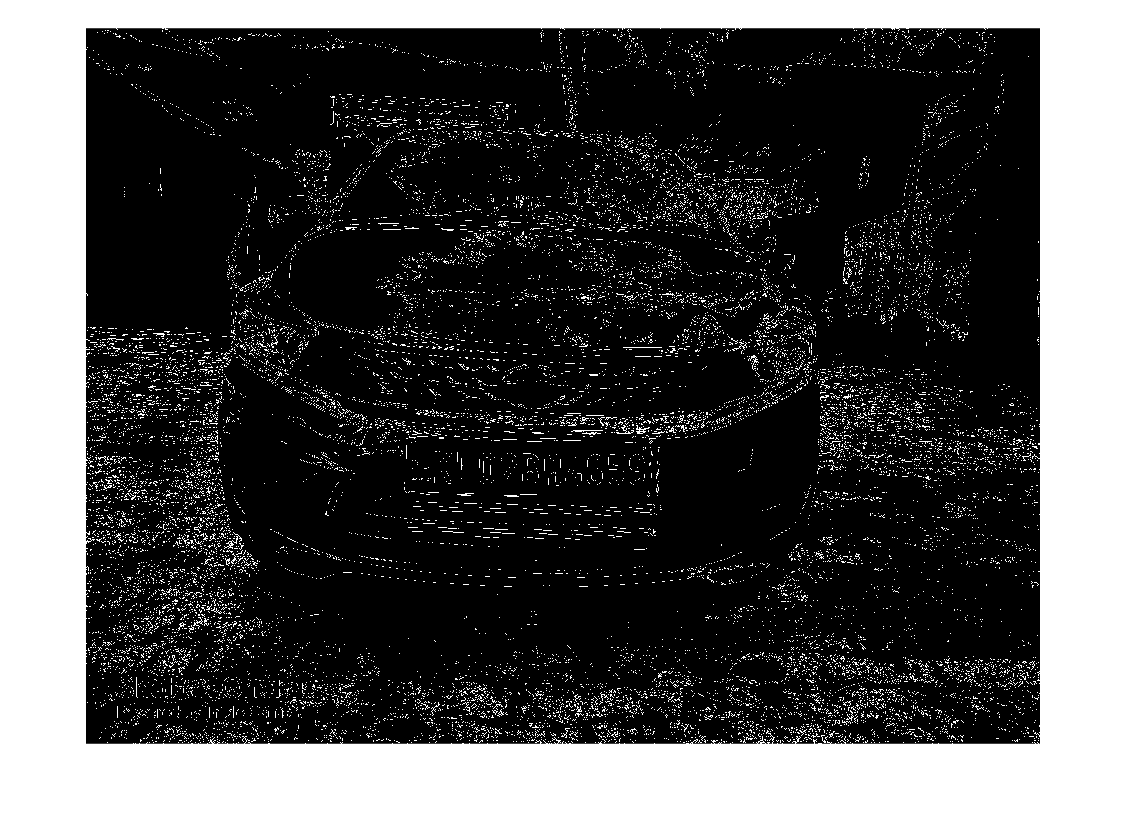

[~,threshold] = edge(mbin,'sobel');
fudgeFactor = 0.7;
BWs = edge(mbin,'sobel',threshold * fudgeFactor);
imshow(BWs)

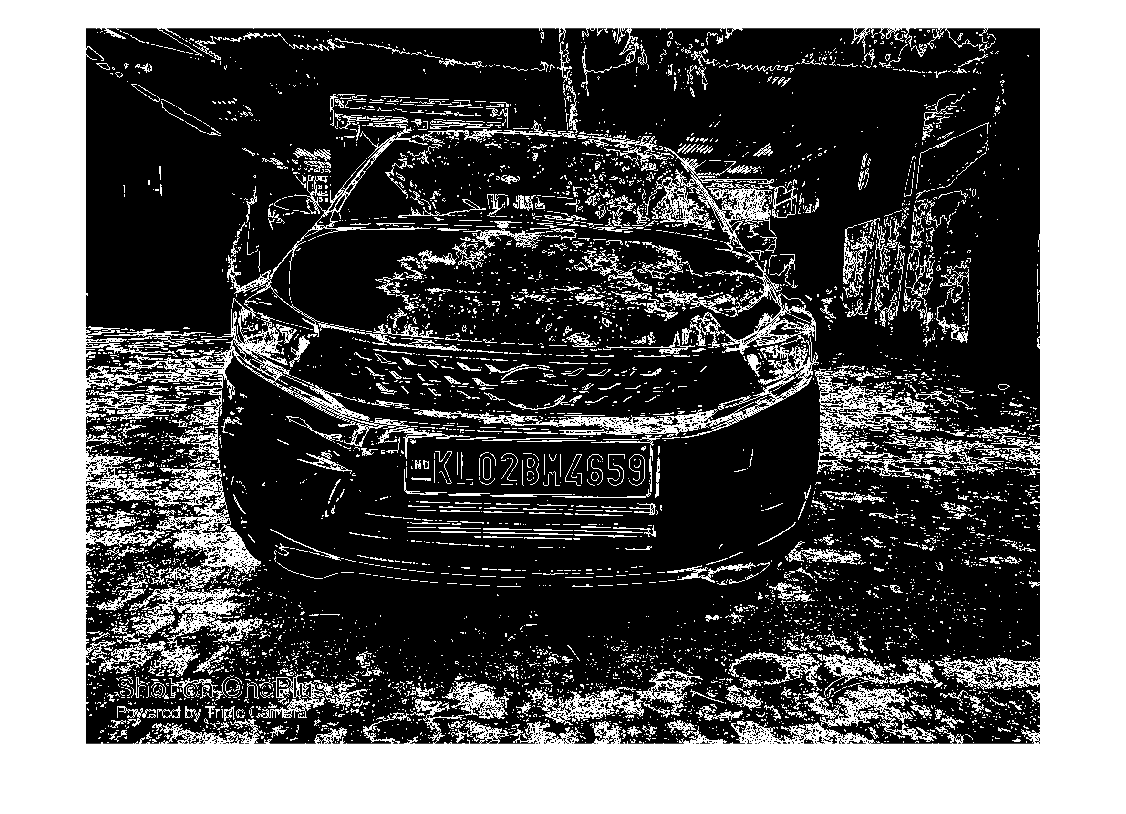

se90 = strel('line',3,90);
se0 = strel('line',3,0);
BWsdil = imdilate(BWs,[se90 se0]);
imshow(BWsdil)

BWnobord = imclearborder(BWsdil, 1);
imshow(BWnobord)

seD = strel('line',2 , fudgeFactor);
BWfinal = imerode(BWnobord,seD);
BWfinal = imerode(BWfinal,seD);
imshow(BWfinal)

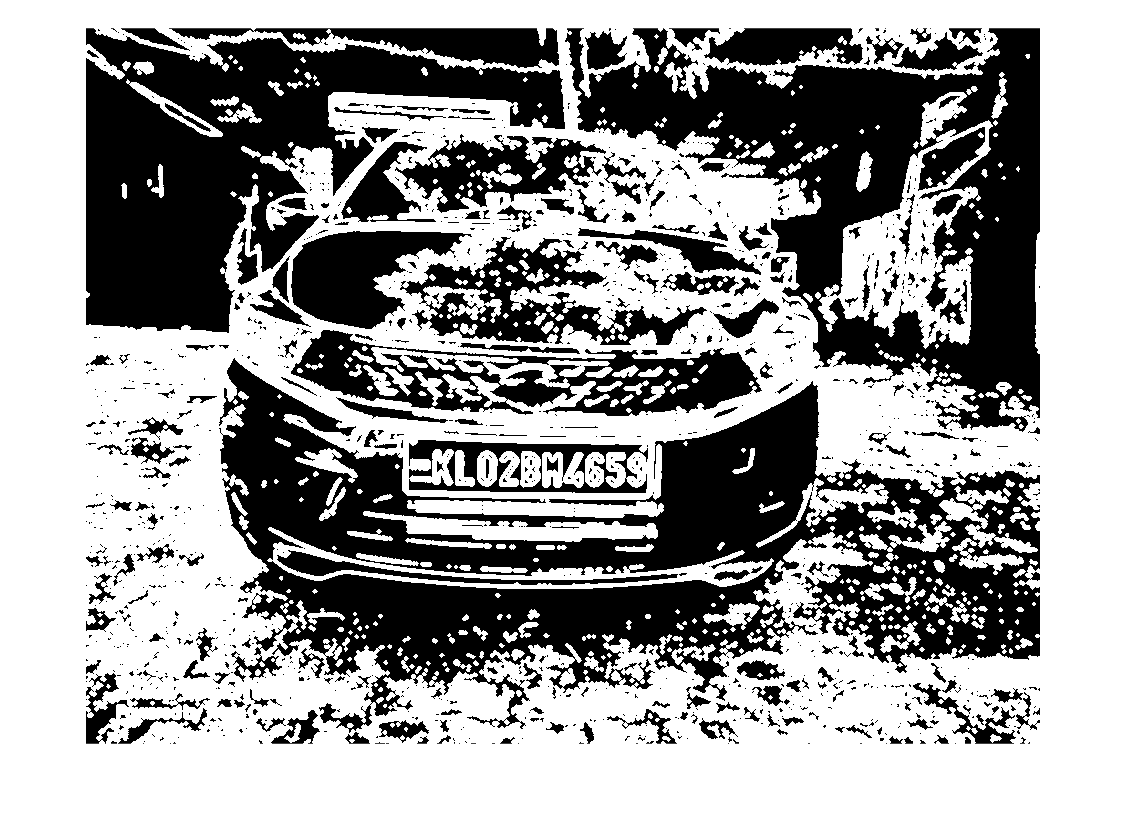

seD = strel('diamond',4);
BWfinal = imdilate(BWfinal,seD);
BWfinal = imdilate(BWfinal,seD);
imshow(BWfinal)

Iprops=regionprops(im,'BoundingBox','Area', 'Image')

Iprops = 32954×1 struct array with fields:
    Area
    BoundingBox
    Image


area = Iprops.Area

area = 4

count = numel(Iprops)

count = 32954

maxa= area;


boundingBox = Iprops.BoundingBox

boundingBox =     0.5000   90.5000    2.0000    4.0000


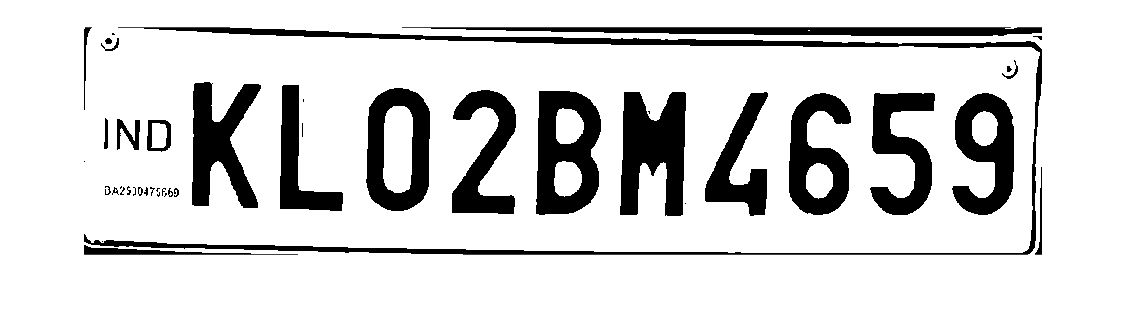

for i=1:count
   if maxa<Iprops(i).Area
       maxa=Iprops(i).Area;
       boundingBox=Iprops(i).BoundingBox;
   end
end    

im = imcrop(mbin, boundingBox);
imshow(im)

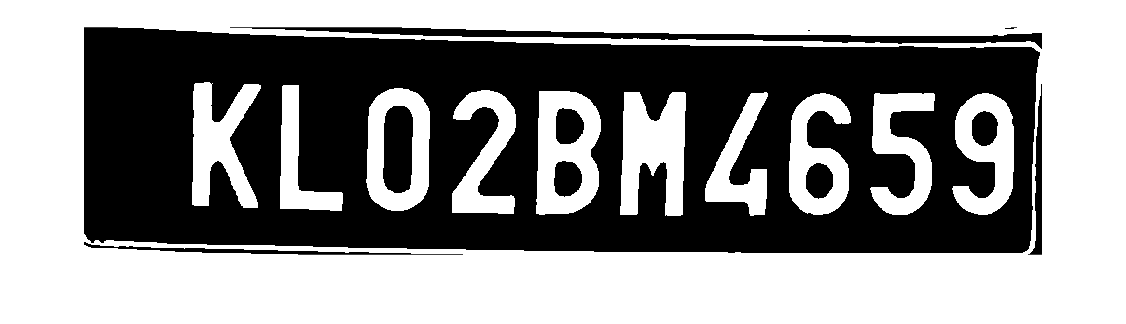

im = bwareaopen(~im, 500); %remove some object if it width is too long or too small than 500

 [h, w] = size(im);

imshow(im);


Iprops=regionprops(im,'BoundingBox','Area', 'Image'); %read letter
count = numel(Iprops);
noPlate=[]; % Initializing the variable of number plate string.

for i=1:count
   ow = length(Iprops(i).Image(1,:));
   oh = length(Iprops(i).Image(:,1));
   if ow<(h/2) & oh>(h/3)
       letter=readLetter(Iprops(i).Image); % Reading the letter corresponding the binary image 'N'.
       noPlate=[noPlate letter] ;% Appending every subsequent character in noPlate variable.
   end
end

ind = 14

ind = 15

ind = 49

ind = 35

ind = 3

ind = 16

ind = 38

ind = 40

ind = 39

ind = 46

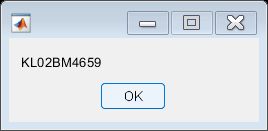

msgbox(noPlate)

function letter=readLetter(snap)

load NewTemplates 
snap=imresize(snap,[42 24]); 
rec=[ ];

for n=1:length(NewTemplates)
    cor=corr2(NewTemplates{1,n},snap); 
    rec=[rec cor]; 
end

ind=find(rec==max(rec));
display(ind);

% Alphabets listings.
if ind==1 || ind==2
    letter='A';
elseif ind==3 || ind==4
    letter='B';
elseif ind==5
    letter='C';
elseif ind==6 || ind==7
    letter='D';
elseif ind==8
    letter='E';
elseif ind==9
    letter='F';
elseif ind==10
    letter='G';
elseif ind==11
    letter='H';
elseif ind==12
    letter='I';
elseif ind==13
    letter='J';
elseif ind==14
    letter='K';
elseif ind==15
    letter='L';
elseif ind==16
    letter='M';
elseif ind==17
    letter='N';
elseif ind==18 || ind==19
    letter='O';
elseif ind==20 || ind==21
    letter='P';
elseif ind==22 || ind==23
    letter='Q';
elseif ind==24 || ind==25
    letter='R';
elseif ind==26
    letter='S';
elseif ind==27
    letter='T';
elseif ind==28
    letter='U';
elseif ind==29
    letter='V';
elseif ind==30
    letter='W';
elseif ind==31
    letter='X';
elseif ind==32
    letter='Y';
elseif ind==33
    letter='Z';
    %*-*-*-*-*
% Numerals listings.
elseif ind==34
    letter='1';
elseif ind==35
    letter='2';
elseif ind==36
    letter='3';
elseif ind==37 || ind==38
    letter='4';
elseif ind==39
    letter='5';
elseif ind==40 || ind==41 || ind==42
    letter='6';
elseif ind==43
    letter='7';
elseif ind==44 || ind==45
    letter='8';
elseif ind==46 || ind==47 || ind==48
    letter='9';
else
    letter='0';
end
end
